clc;
clear;
close all;

% --- KONFİGÜRASYON ---   UPLINK 
M_verici = 4;                 % Sabit verici anten sayısı
M_alici_vektoru = [4, 8, 16]; % Karşılaştırılacak alıcı anten sayıları

% Modülasyon Parametreleri
N_qam = 4; % 4-QAM (QPSK)
bit_per_sym = log2(N_qam);

% Simülasyon Kontrol Parametreleri
SNR_dB = 0:2:20; 
num_iteration = 5000; 
sym_per_iteration = 1000; 

% Veri hazırlığı
bits_per_stream = sym_per_iteration * bit_per_sym;
BER_results = zeros(length(SNR_dB), length(M_alici_vektoru));

% --- SİMÜLASYON DÖNGÜSÜ ---
for k = 1:length(M_alici_vektoru)
    M_alici = M_alici_vektoru(k); 
    fprintf('Hesaplanıyor: %d x %d MIMO Yapısı...\n', M_verici, M_alici);

    for i = 1:length(SNR_dB)
        SNR_linear = 10^(SNR_dB(i) / 10);
        P_noise = 1 / SNR_linear;
        total_errors = 0;
        total_bits_processed = 0;

        for j = 1:num_iteration
            % Veri oluşturma (Tüm antenler için toplam bit)
            tx_bits = randi([0 1], bits_per_stream * M_verici, 1);
            X_vec = qammod(tx_bits, N_qam, 'gray', 'InputType', 'bit', 'UnitAveragePower', true);
            X_last = reshape(X_vec, [], M_verici); % Sembolleri antenlere dağıt

            % Kanal ve Gürültü
            H = (randn(M_alici, M_verici) + 1i * randn(M_alici, M_verici)) / sqrt(2);
            N_mat = (randn(M_alici, sym_per_iteration) + 1i * randn(M_alici, sym_per_iteration)) * sqrt(P_noise / 2);

            % İletim
            Y = H * (X_last.') + N_mat;
            
            % ALICI (ZF COMBINING)
            W_zf = pinv(H); 
            Y_combined = W_zf * Y;
            
            % Demodülasyon
            rx_bits = qamdemod(Y_combined.', N_qam, 'gray', 'OutputType', 'bit', 'UnitAveragePower', true);
            
            [num_errors, ~] = biterr(tx_bits, rx_bits(:));
            total_errors = total_errors + num_errors;
            total_bits_processed = total_bits_processed + length(tx_bits);
        end 
        BER_results(i, k) = total_errors / total_bits_processed;
    end 
end

Hesaplanıyor: 4 x 4 MIMO Yapısı...
Hesaplanıyor: 4 x 8 MIMO Yapısı...
Hesaplanıyor: 4 x 16 MIMO Yapısı...


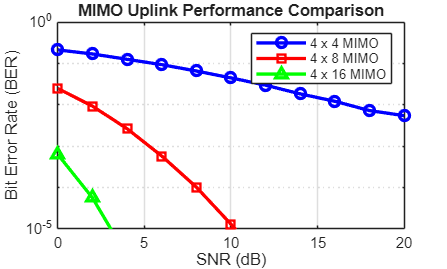


% --- GRAFİK DÜZENLEME ---
figure;
semilogy(SNR_dB, BER_results(:, 1), 'o-b', 'LineWidth', 2, 'MarkerSize', 6); hold on;
semilogy(SNR_dB, BER_results(:, 2), 's-r', 'LineWidth', 2, 'MarkerSize', 6);
semilogy(SNR_dB, BER_results(:, 3), '^-g', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
hold off;


xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('MIMO Uplink Performance Comparison'); 

% Legend (İsimlendirme) kısmını anten sayılarına göre dinamik hale getirdik
legend(sprintf('%d x %d MIMO', M_verici, M_alici_vektoru(1)), ...
       sprintf('%d x %d MIMO', M_verici, M_alici_vektoru(2)), ...
       sprintf('%d x %d MIMO', M_verici, M_alici_vektoru(3)), ...
       'Location', 'northeast', 'FontSize', 8);


xlim([min(SNR_dB) max(SNR_dB)]);
ylim([(1e-5 - 1e-16) 1]);